l_0 = 0.5;
rho = 0.0254;

N_segments = 3;
arm_series = ArmSeriesFactory.constant_2d_muscle_arm(N_segments, rho, l_0);
arm_series.set_mechanics(BasicPolyBellowMechanics(l_0));
g_tip_goal = Pose2.hat([0.3; -0.2; 0]);

% optimize simple arm for a single target pose
Q = [0; -0.25; 0];

[residual, pressures] = evaluate_arm(arm_series, {g_tip_goal}, Q);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 13.471646 seconds.


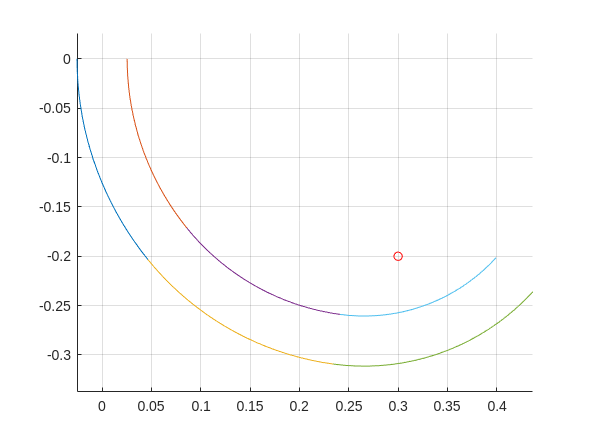

arm_series.solve_equilibrium_gina(pressures, Q, "print", false);
Plotter2D.plot_arm_series(arm_series, axes(figure()));
goal_coords = Pose2.vee(g_tip_goal);
scatter(goal_coords(1), goal_coords(2), 'ro');

disp(pressures)

   14.5752
    0.0001


% optimize simple arm for a list of target poses
Q = [0; 0; 0];
g_tip_goal_1 = Pose2.hat([0.3; -0.2; 0]);
g_tip_goal_2 = Pose2.hat([0.3; -0.3; 0]);
g_tip_goal_3 = Pose2.hat([0.3; -0.4; 0]);
g_targets = {g_tip_goal_1, g_tip_goal_2, g_tip_goal_3};

[residuals, pressures_no_load] = evaluate_arm(arm_series, g_targets, Q);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 4.527078 seconds.

Local minimum found that satisfies the constraints.

Optimization 

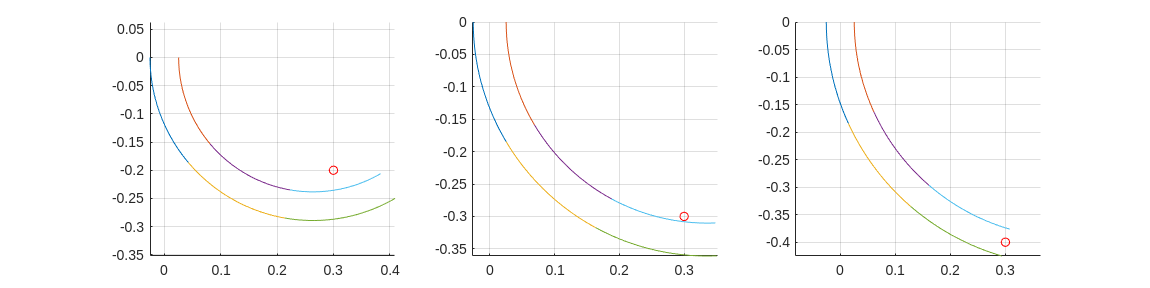

plot_arms(arm_series, pressures_no_load, g_targets, Q);

disp(pressures_no_load)

    8.5241    6.5465    5.5940
    0.0001    0.0001    0.3634


Q = [0; -0.25; 0];
[residuals, pressures_small_load] = evaluate_arm(arm_series, g_targets, Q);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 12.663312 seconds.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

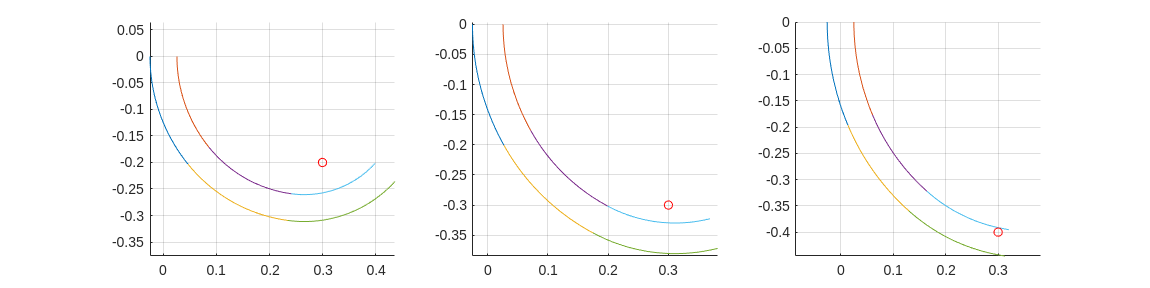

plot_arms(arm_series, pressures_small_load, g_targets, Q);

disp(pressures_small_load)

   14.5752   12.0506    9.9558
    0.0001    0.0004    0.0022


Q = [0; -1; 0];

[residuals, pressures_large_load] = evaluate_arm(arm_series, g_targets, Q);

Nonzero residual detected. Printing: 
   -0.0015   -0.0041   -0.0041
    0.0000    0.0000   -0.0000
    0.0727    0.1753    0.2533
Nonzero residual detected. Printing: 
   -0.0011   -0.0047   -0.0038
    0.0000    0.0000   -0.0000
    0.0526    0.1766    0.2384
Nonzero residual detected. Printing: 
   -0.0024   -0.0035   -0.0042
    0.0000    0.0000   -0.0000
    0.1084    0.1718    0.2763

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

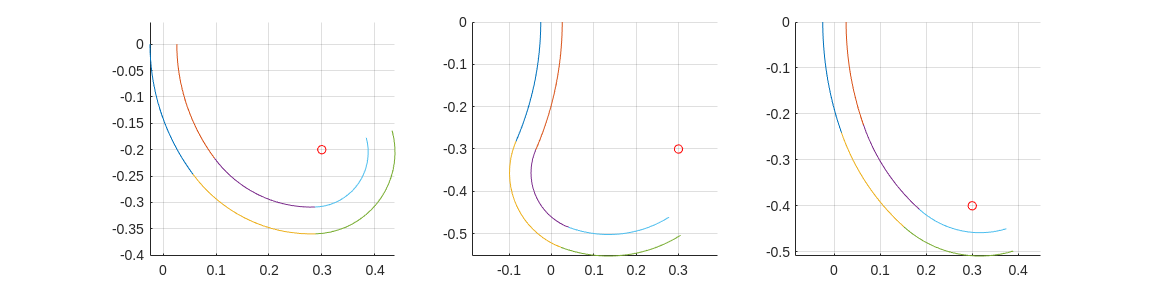


plot_arms(arm_series, pressures_large_load, g_targets, Q)

% Now consider an antagonistic arm
antagonist_arm = ArmSeriesFactory.constant_2d_antagonist_arm(3, 0.0254, 0.01, 0.5);
antagonist_arm.set_mechanics(BasicPolyBellowMechanics(l_0), [1,4]);
antagonist_arm.set_mechanics(GinaMuscleMechanics(l_0), [2,3]);

[residuals, pressures_antagonism] = evaluate_arm(antagonist_arm, g_targets, Q);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 132.981504 seconds.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function 

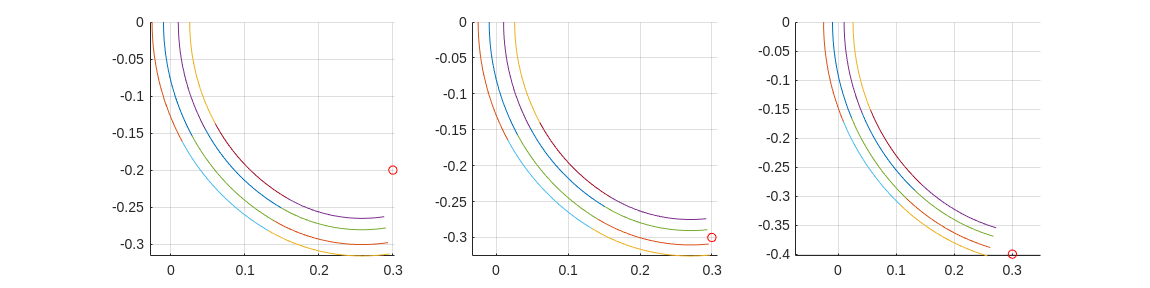

plot_arms(antagonist_arm, pressures_antagonism, g_targets, Q)

antagonist_arm_wider = ArmSeriesFactory.constant_2d_antagonist_arm(3, 0.0254, 0.02, 0.5);
antagonist_arm_wider.set_mechanics(BasicPolyBellowMechanics(l_0), [1,4]);
antagonist_arm_wider.set_mechanics(GinaMuscleMechanics(l_0), [2,3]);

[residuals, pressures_antagonism] = evaluate_arm(antagonist_arm_wider, g_targets, Q);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Elapsed time is 175.104172 seconds.


plot_arms(antagonist_arm, pressures_antagonism, g_targets, Q)

function plot_arms(arm_series, pressures, g_targets, Q)
    fig = figure();
    set(fig, "Position", [0, 0, 1600, 400]);
    for i = 1 : length(g_targets)
        ax = subplot(1, length(g_targets), i);
        arm_series.solve_equilibrium_gina(pressures(:, i), Q, "print", false);
        Plotter2D.plot_arm_series(arm_series, ax);
        
        g_target_i = g_targets{i};
        coords = Pose2.vee(g_target_i);
        scatter(coords(1), coords(2), 'ro');
    end
end